Задание 1

k_avg = 0;
Tm_avg = 0;
battery_power = 7.5; % Заряд батареи, полученный с брика
for i = -5:5
    if i ~= 0
        data = readmatrix("C:\Users\nambo\Desktop\тау6\data_mnk/mnk_data"+i*20);
        time = data(:,1);
        angle = data(:,2)*pi/180; % перевод из градусов в радианы
        speed = data(:,3)*pi/180; % перевод из градусов в радианы
        par0=[2;0.077]; % предполагаемые значения k и Tm соответсвенно
        U_volts = i*20*battery_power/100;
        fun_angle = @(par,time)U_volts*par(1)*(time - par(2)*(1 - exp(-time/par(2)))); %функция для апроксимации по углу
        par = lsqcurvefit(fun_angle,par0,time,angle); % апроксимация с помощью МНК
        k = par(1);
        Tm = par(2);
        k_avg = k + k_avg;
        Tm_avg = Tm + Tm_avg;
    end
end


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

Tm_avg = Tm_avg/10

Tm_avg = 0.0625

k_avg = k_avg/10

k_avg = 1.7373

Задание 3

syms s t
k_avg =1;
Tm_avg=1;
g = 0.5*sin(3*t)*cos(5*t)
Wo = k_avg/(Tm_avg*s^2+s)
[WoNum, WoDen] = numden(Wo)
[WgNum, WgDen] = numden(laplace(g))
syms c c0
WrDen = c * WgDen * (s+c0)
syms c1 c2 c3 c4 c5 c6
WrNum = c1*s^5 + c2*s^4 + c3*s^3 + c4*s^2 + c5*s + c6
pol = coeffs(WrNum*WoNum+ WrDen*WoDen, s, 'All')
polaa = WrNum*WoNum+ WrDen*WoDen
neededPol = coeffs((s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1)*(s+1), s, 'All')
sol = solve(pol == neededPol)

WrNumSol = sym2poly(subs(WrNum, [c c0 c1 c2 c3 c4 c5 c6], [sol.c sol.c0 sol.c1 sol.c2 sol.c3 sol.c4 sol.c5 sol.c6]))
WrDenSol = sym2poly(subs(WrDen, [c c0], [sol.c sol.c0]))

simtime = 40;
first = sim("Task2spec.slx", simtime)
hold on
plot(first.y.Time, first.y.Data, 'green')
plot(first.e.Time, first.e.Data, 'red')
plot(first.g.Time, first.g.Data, 'blue')

xlabel("Time, s")
ylabel("Out")
grid on
title('g(t) = 2*sin(3t)*cos(5t)')
legend("y(t)", "e(t)", "g(t)")


4

T=1;
kp=1;

% считаем частоту при которой амплитуда = 1
syms x;
s=x*j;
ws=(kp)./(T*s.^2+s); %вставить передаточную сюда
A=sqrt(real(ws).^2+imag(ws).^2);
wkrit=double(solve(A==1,x>0)) %w при которой A=1

wkrit = 0.7862

% 
x=wkrit

x = 0.7862

s=x*j;
ws=(kp)./(T*s.^2+s); %вставить передаточную сюда
F=atan2(imag(ws),real(ws))+pi 

F = 0.9046

tmax=double(F/wkrit) %критическая задержка

tmax = 1.1506

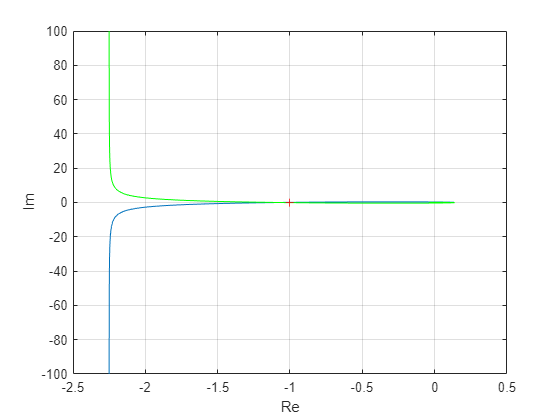



delta = 0.1;
t1 = tmax+delta; % время задержки 1
t2 = tmax-delta; % время задержки 2
%% график с критической задержкой + дельта
x=0:0.01:10;
delay = exp(-t1.*(x*j));
s=x*j;
ws=(kp)./(T*s.^2+s); %вставить передаточную сюда

%% график с критической задержкой - дельта
W1 = delay.*ws; 
plot(real(W1), imag(W1), real(W1), -imag(W1), "-g", -1, 0,'r+')
grid
xlabel("Re")
ylabel("Im")

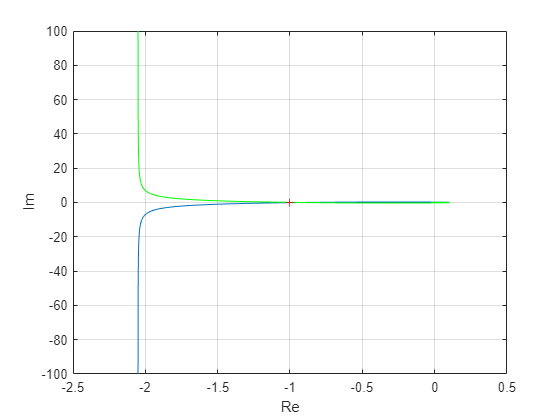

%%
delay = exp(-t2.*(x*j));
s=x*j;
ws=(kp)./(T*s.^2+s); %вставить передаточную сюда

W1 = delay.*ws; 
plot(real(W1), imag(W1), real(W1), -imag(W1), "-g", -1, 0,'r+')
grid
xlabel("Re")
ylabel("Im")


%%передаточная с задержками
syms s;
ws=(kp)./(T*s.^2+s);%вставить передаточную сюда
simplifyFraction(ws,"Expand",true);
%разомкнутая(разбиваем на кф, чтобы норм годограф строить)
[nopen, dopen] = numden(ws);
Nopen=sym2poly(nopen);
Dopen=sym2poly(dopen);
Wopen=tf(Nopen,Dopen)

Wopen =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



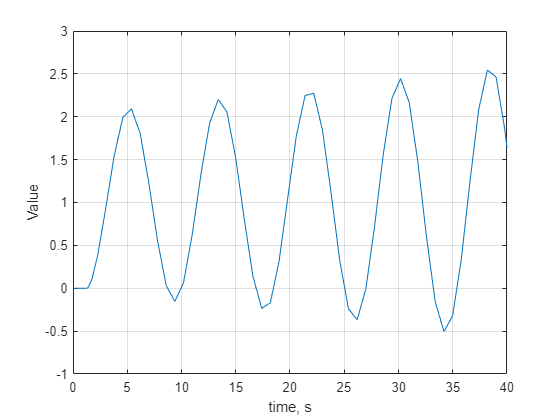



simtime = 40;
b = sim('lab6_4.slx', simtime);
plot(b.y0.Time, b.y0.Data)

xlabel("time, s")
ylabel("Value")
grid on

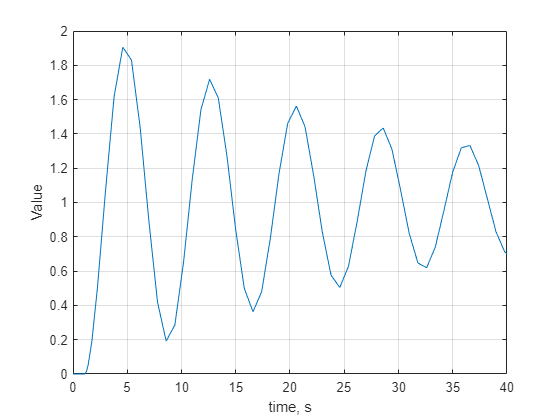


simtime = 40;
b = sim('lab6_4.slx', simtime);
plot(b.y1.Time, b.y1.Data)

xlabel("time, s")
ylabel("Value")
grid on


%% эксп. график с критической задержкой - дельта
data = readmatrix("") %%вставить путь сюда

Error using readmatrix
Unable to find or open ''. Check the path and filename or file permissions.

time = data(:,1);
angle = data(:,2)*pi/180;
plot(time, angle);

%% эксп. график с критической задержкой + дельт
data = readmatrix("") %%вставить путь сюда
time = data(:,1);
angle = data(:,2)*pi/180;
plot(time, angle);